# MECH 6326 - HW2

Jonas Wagner

clear
close all

## Problem 4

% Setup
P = [
    0.75 0.05 0.25 0 0
    0.05 0.15 0.3 0.15 0
    0.2 0.15 0.1 0 0.2
    0 0.65 0 0.4 0.35
    0 0 0.35 0.45 0.45
];
p_0 = [1 0 0 0 0];

## Part 1

N = 50;
% P(x_N = 1)
p_N = p_0 * P^N

p_N =     0.1428    0.1428    0.1428    0.1428    0.1428


fprintf('P(x_k = 1) = %f\n',p_N(1))

P(x_k = 1) = 0.142756


for k=1:N
    p_all(k,:) = p_0 * P^k;
end
p_avg = mean(p_all,1);
fprintf('Average P(x_k = 1) = %f\n', p_avg(1))

Average P(x_k = 1) = 0.197995


## Part 2

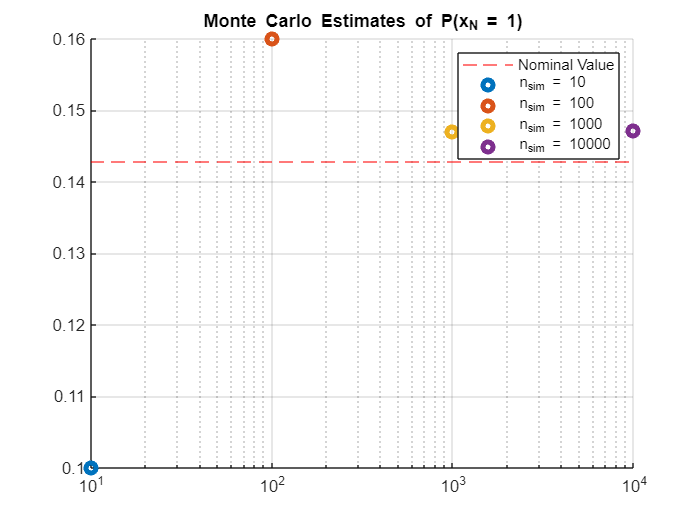

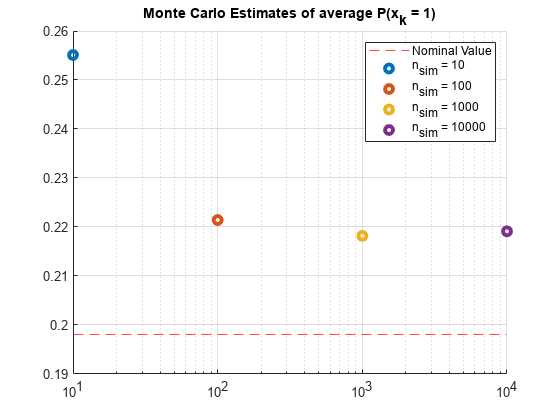

Monte Carlo with 10 simulations:


P(x_N = 1) = 0.1


Average P(x_k = 1) = 0.2551


Monte Carlo with 100 simulations:


P(x_N = 1) = 0.16


Average P(x_k = 1) = 0.22143


Monte Carlo with 1000 simulations:


P(x_N = 1) = 0.147


Average P(x_k = 1) = 0.2182


Monte Carlo with 10000 simulations:


P(x_N = 1) = 0.1472


Average P(x_k = 1) = 0.21912


figure(1); hold on; grid on;
title('Monte Carlo Estimates of P(x_N = 1)');
legend();
yline(p_N(1),'r--', 'DisplayName', 'Nominal Value');
set(gca, 'xscale', 'log')

figure(2); hold on; grid on;
title('Monte Carlo Estimates of average P(x_k = 1)');
legend();
yline(p_avg(1),'r--', 'DisplayName', 'Nominal Value');
set(gca, 'xscale', 'log')


N = 50;
x_0 = 1;
for n_sim = [10,100,1000,10000]
    rng(1);% set standard seed
    X = zeros(n_sim,N);
    for j = 1:n_sim
        X(j,1) = x_0;
        for i = 2:N
            X(j,i) = find(rand < cumsum(P(:,X(j,i-1))),1); % complicated... but essentially just selecting randomly acording to the probability expected for current state
        end
    end
    % P(x_N = 1)
    p_N_1 = sum(X(:,N)==1)/n_sim;
    % Average P(x_k = 1)
    p_avg_1 = sum(sum(X==1,2)/(N-1))/n_sim;

    % Display Results
    disp(['Monte Carlo with ', num2str(n_sim), ' simulations:'])
    disp(['P(x_N = 1) = ', num2str(p_N_1)])
    disp(['Average P(x_k = 1) = ', num2str(p_avg_1)])

    % Plot Final Results
    figure(1);
    plot( ...
        n_sim, p_N_1, 'o', 'LineWidth', 3, ...
        'DisplayName', ['n_{sim} = ', num2str(n_sim)])

    figure(2);
    plot( ...
        n_sim, p_avg_1, 'o', 'LineWidth', 3, ...
        'DisplayName', ['n_{sim} = ', num2str(n_sim)])
end